# BEV System Model - Simulation Case

modelName = "BEV_system_model";
load_system(modelName)
BEV_useComponents_Basic

Use Basic models for all components.


VehSpdRef_loadSimulationCase_Constant( ...
  ModelName = modelName, ...
  TargetSubsystemPath = ...
    "/Controller & Environment" + ...
    "/Vehicle speed reference" )

Setting up simulation...
Simulation case: Constant
Setting simulation stop time to 1000 sec.
Selecting simulation case 5.


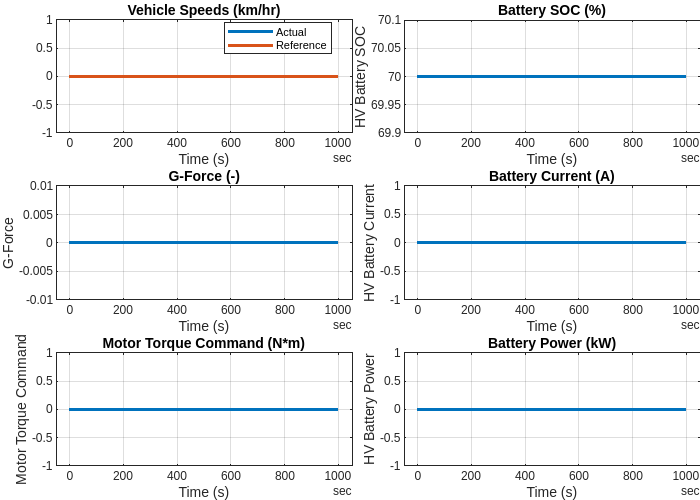

simOut = sim(modelName);
simData = extractTimetable(simOut.logsout);
fig = BEV_plotResultsCompact( SimData = simData, PlotTemperature = false );

*Copyright 2023 The MathWorks, Inc.*